clear tbl; clear altitude; clear distance;
load dati2.txt
tbl = readtable('dati2.txt')

tbl = 8×2 table
    Var1    Var2
    ____    ____

      0     100 
      1     300 
      3     500 
      5     700 
      6     900 
      8     700 
      9     450 
     10     300 


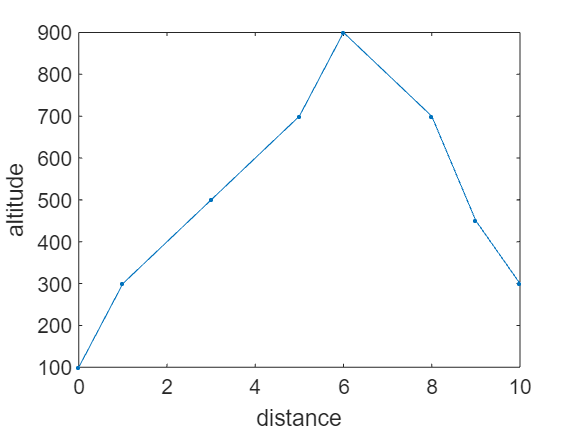


plot(tbl.Var1,tbl.Var2,'Marker','.','LineStyle','-');
xlabel('distance');ylabel('altitude')

d = tbl.Var1

d =      0
     1
     3
     5
     6
     8
     9
    10


q = tbl.Var2

q =    100
   300
   500
   700
   900
   700
   450
   300




Cal = 50

Cal = 50

c(1:length(d)) = 0

c =      0     0     0     0     0     0     0     0


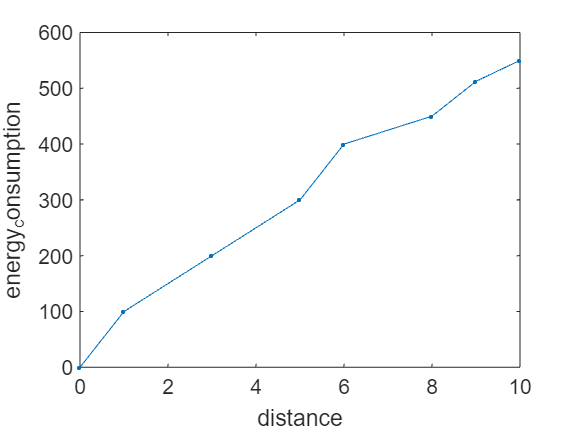


for i =2:length(d)
if (q(i) - q(i-1))>=0
        c(i) = c(i-1) + (q(i) - q(i-1))/100*Cal;
else
        c(i) = c(i-1) - (q(i) - q(i-1))/100*Cal/2;
end

end

figure(2)
plot(d,c,'Marker','.')
xlabel('distance');ylabel('energy_consumption')

plot the motion of a falling ball up to the point where it hits the ground. you may not know the no. of steps that are needed before it hits the ground . if the position of the ball is x(t) = 100.0 - 4.9*t^2. calculate the position as a function of time in steps of dt as long as x is positive


t0  = 0.0;t1 =10.0; %initializing time
dt = 0.01;
n = ceil((t1-t0)/dt) + 1 %rounding up to infinity

n = 1001

t = zeros(n,1)

t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y = zeros(n,1)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


 i =1;
 t(1) = t0

t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


 y(1) = 100.0  - 4.9*t(1)^2

y =    100
     0
     0
     0
     0
     0
     0
     0
     0
     0


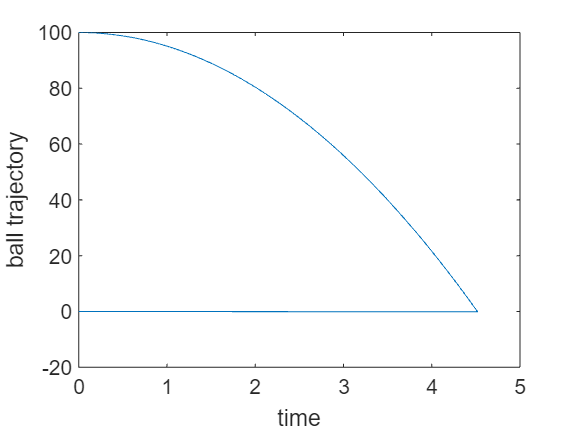

 while y(i)>0.0 % descend of distance and descend of time
     i = i +1;
     t(i)  =t0 + (i-1)*dt;
     y(i) = 100.0 - 4.9*t(i)^2;
 end
 plot(t,y);xlabel("time");ylabel("ball trajectory")